
--- Normální ---


Průměr (ručně): -0.0293 | MATLAB: -0.0293


Rozptyl (ručně): 0.9580 | MATLAB: 0.9580


Geometrický: 0.4770


Harmonický: 0.1701


Šikmost: 0.1517


Špičatost: 3.1584


Medián: -0.0054


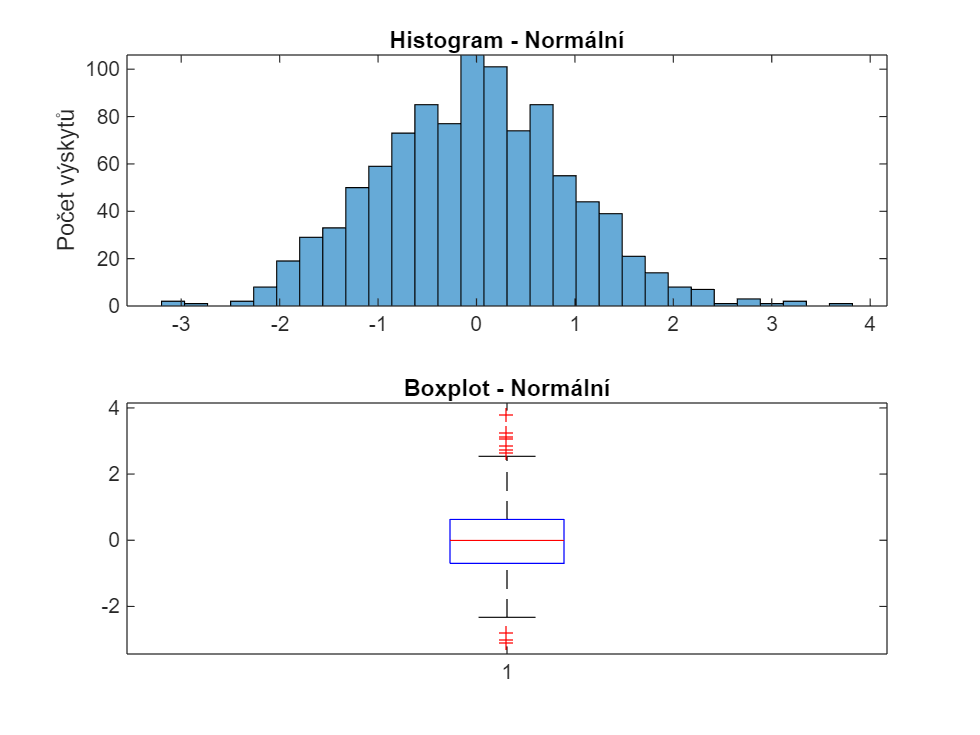


--- Normální ---


Průměr (ručně): -0.0293 | MATLAB: -0.0293


Rozptyl (ručně): 0.9580 | MATLAB: 0.9580


Geometrický: 0.4770


Harmonický: 0.1701


Šikmost: 0.1517


Špičatost: 3.1584


Medián: -0.0054



--- Rovnoměrné ---


Průměr (ručně): 0.5098 | MATLAB: 0.5098


Rozptyl (ručně): 0.0820 | MATLAB: 0.0820


Geometrický: 0.3826


Harmonický: 0.0643


Šikmost: -0.0147


Špičatost: 1.8224


Medián: 0.5177


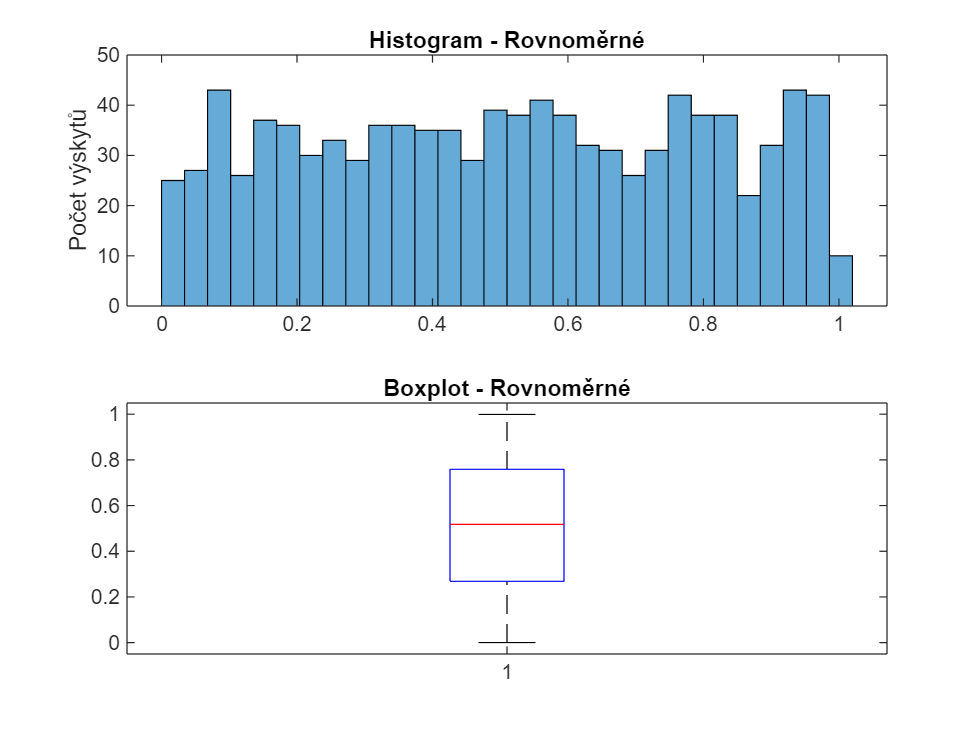


--- Rovnoměrné ---


Průměr (ručně): 0.5098 | MATLAB: 0.5098


Rozptyl (ručně): 0.0820 | MATLAB: 0.0820


Geometrický: 0.3826


Harmonický: 0.0643


Šikmost: -0.0147


Špičatost: 1.8224


Medián: 0.5177



--- Exponenciální ---


Průměr (ručně): 1.0021 | MATLAB: 1.0021


Rozptyl (ručně): 0.9992 | MATLAB: 0.9992


Geometrický: 0.5828


Harmonický: 0.1703


Šikmost: 2.1176


Špičatost: 9.7962


Medián: 0.6593


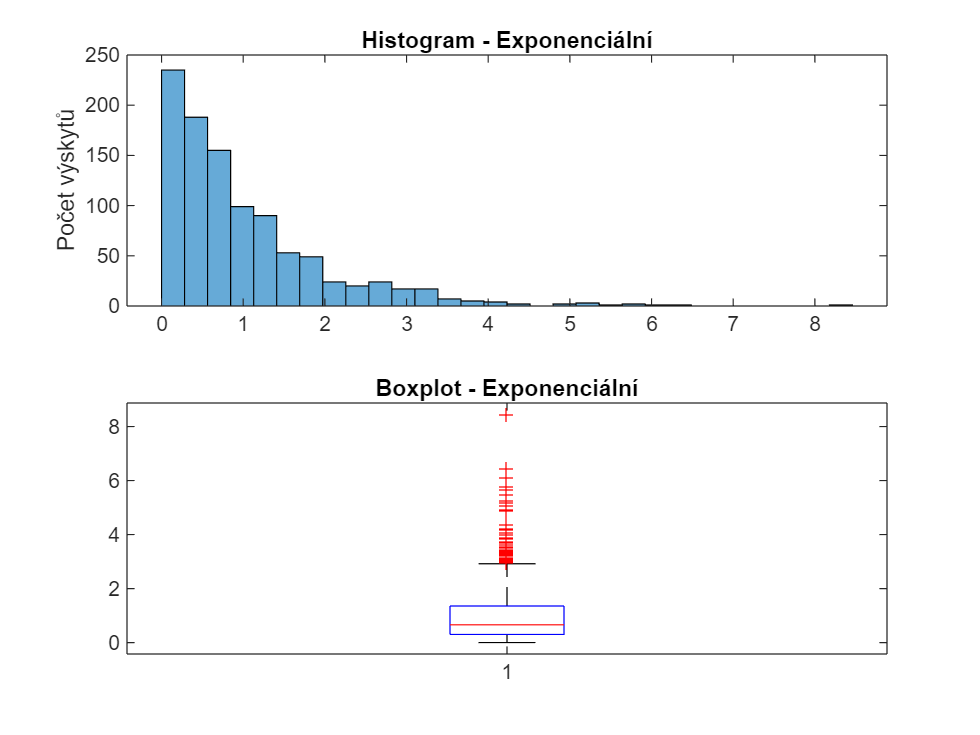


--- Exponenciální ---


Průměr (ručně): 1.0021 | MATLAB: 1.0021


Rozptyl (ručně): 0.9992 | MATLAB: 0.9992


Geometrický: 0.5828


Harmonický: 0.1703


Šikmost: 2.1176


Špičatost: 9.7962


Medián: 0.6593



--- Beta ---


Průměr (ručně): 0.2910 | MATLAB: 0.2910


Rozptyl (ručně): 0.0247 | MATLAB: 0.0247


Geometrický: 0.2408


Harmonický: 0.1731


Šikmost: 0.4757


Špičatost: 2.7393


Medián: 0.2792


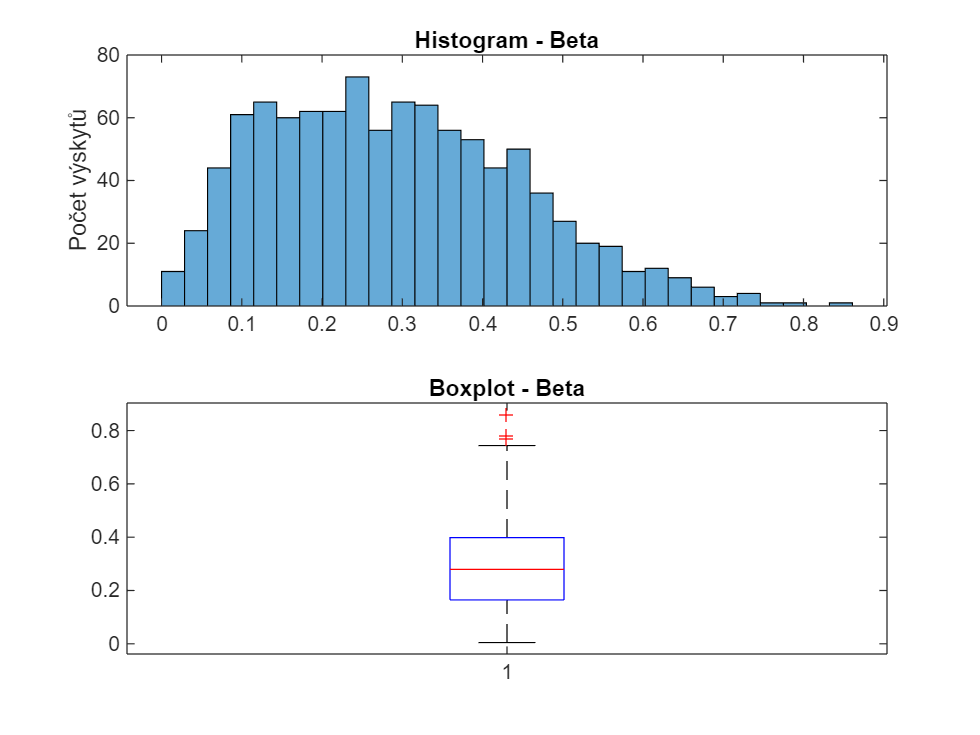


--- Beta ---


Průměr (ručně): 0.2910 | MATLAB: 0.2910


Rozptyl (ručně): 0.0247 | MATLAB: 0.0247


Geometrický: 0.2408


Harmonický: 0.1731


Šikmost: 0.4757


Špičatost: 2.7393


Medián: 0.2792



--- Gamma ---


Průměr (ručně): 4.0019 | MATLAB: 4.0019


Rozptyl (ručně): 7.6417 | MATLAB: 7.6417


Geometrický: 3.0436


Harmonický: 1.8180


Šikmost: 1.2126


Špičatost: 4.7089


Medián: 3.3530


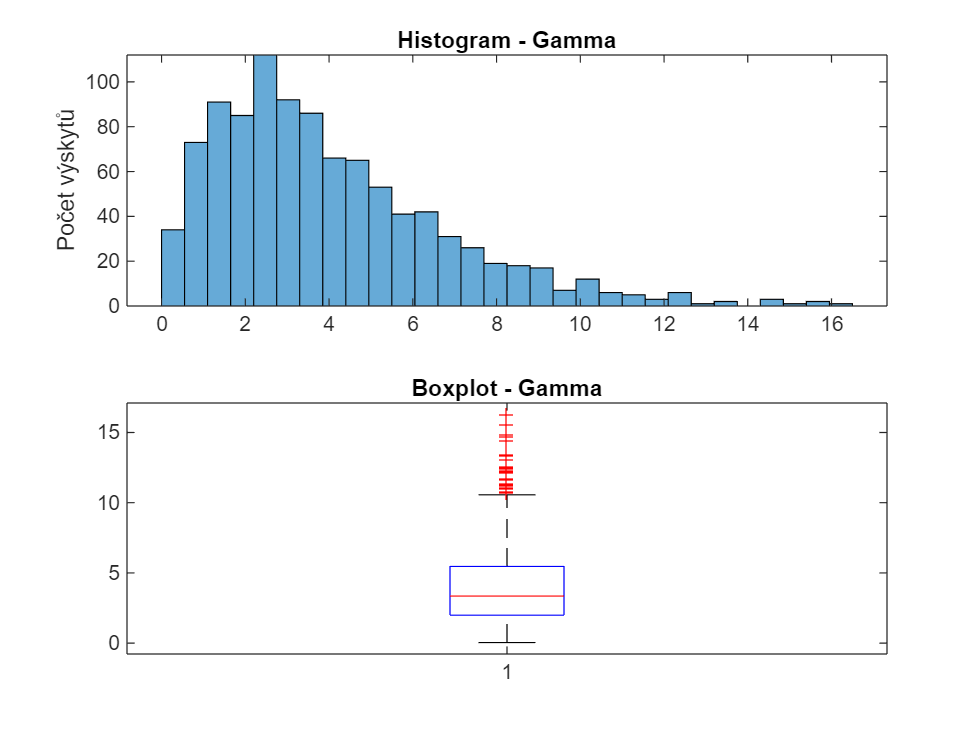


--- Gamma ---


Průměr (ručně): 4.0019 | MATLAB: 4.0019


Rozptyl (ručně): 7.6417 | MATLAB: 7.6417


Geometrický: 3.0436


Harmonický: 1.8180


Šikmost: 1.2126


Špičatost: 4.7089


Medián: 3.3530



--- Binomické ---


Průměr (ručně): 4.9860 | MATLAB: 4.9860


Rozptyl (ručně): 2.4823 | MATLAB: 2.4823


Geometrický: 4.7327


Harmonický: 4.3998


Šikmost: -0.0860


Špičatost: 2.8995


Medián: 5.0000


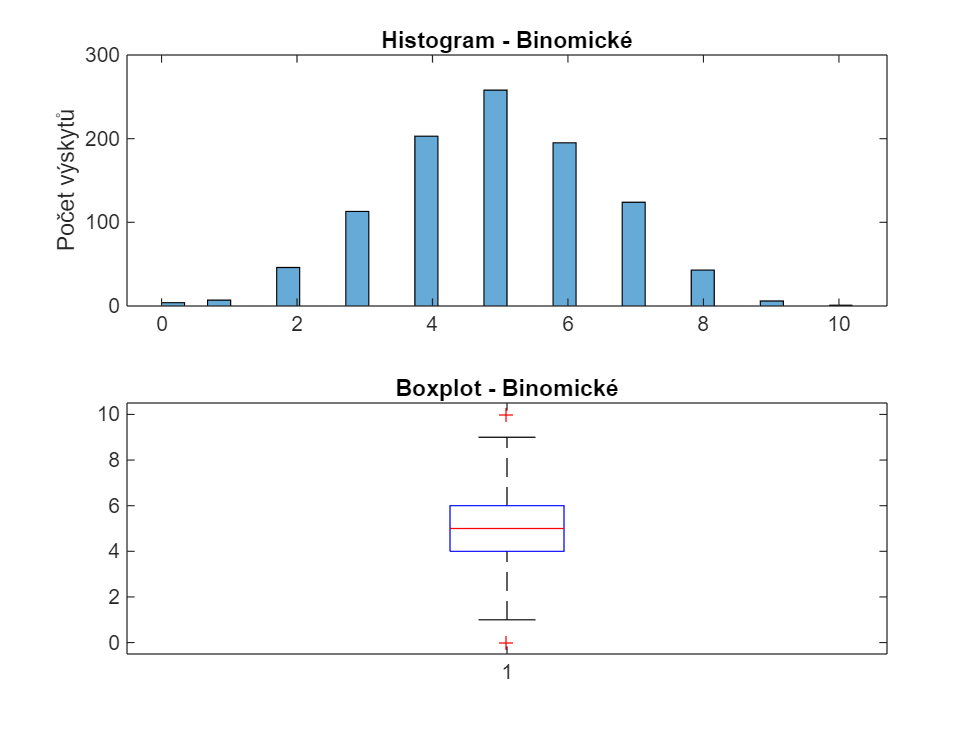


--- Binomické ---


Průměr (ručně): 4.9860 | MATLAB: 4.9860


Rozptyl (ručně): 2.4823 | MATLAB: 2.4823


Geometrický: 4.7327


Harmonický: 4.3998


Šikmost: -0.0860


Špičatost: 2.8995


Medián: 5.0000


% Statisticke zpracovani dat – projekt
% Skript analyzuje šest různých náhodných rozdělení dat.
% Cílem je ukázat, jak různé charakteristiky popisují statistické vlastnosti těchto rozdělení.
% Některé výpočty (průměr, rozptyl) jsou provedeny ručně pro demonstraci porozumění základním statistickým principům.

clear; clc; close all;

%% Generování náhodných dat
% Pro analýzu použijeme 6 různých typů rozdělení pravděpodobnosti,
% abychom demonstrovali rozdílné vlastnosti dat (např. symetrie, šikmost, koncentrace kolem středu).

data_normal = randn(1, 1000);                     % Normální (Gaussovo) rozdělení – symetrické, střed 0
data_uniform = rand(1, 1000);                     % Rovnoměrné rozdělení – stejnoměrné pokrytí intervalu
data_exponential = exprnd(1, 1, 1000);            % Exponenciální rozdělení – kladná šikmost
data_beta = betarnd(2, 5, 1, 1000);               % Beta rozdělení – ohraničené, šikmé
data_gamma = gamrnd(2, 2, 1, 1000);               % Gamma rozdělení – kladně šikmé, pozorovatelné u čekacích dob
data_binomial = binornd(10, 0.5, 1, 1000);        % Binomické rozdělení – diskrétní, počet úspěchů

% Data uložíme do buňky spolu s názvem pro pozdější zpracování
datasets = {
    'Normální', data_normal;
    'Rovnoměrné', data_uniform;
    'Exponenciální', data_exponential;
    'Beta', data_beta;
    'Gamma', data_gamma;
    'Binomické', data_binomial
};

%% Inicializace polí pro statistické charakteristiky
% Budeme uchovávat statistiky pro každou množinu pro pozdější porovnání

labels = {};              % Názvy rozdělení
means = [];               % Aritmetické průměry (vestavěná funkce)
means_manual = [];        % Aritmetické průměry (ručně)
variances = [];           % Rozptyl (MATLAB)
variances_manual = [];    % Rozptyl (ručně)
geomeans = [];            % Geometrické průměry
harmmeans = [];           % Harmonické průměry
skewnesses = [];          % Šikmost
kurtoses = [];            % Špičatost
medians = [];             % Mediány (2. kvartil)

%% Výpočet a výpis statistických charakteristik
for i = 1:size(datasets,1)
    label = datasets{i,1};
    data = datasets{i,2};

    labels{end+1} = label;

    % Aritmetický průměr – ručně
    mean_manual = sum(data) / length(data);
    means_manual(end+1) = mean_manual;

    % Aritmetický průměr – MATLAB funkcí
    means(end+1) = mean(data);

    % Rozptyl – ručně
    var_manual = sum((data - mean_manual).^2) / (length(data)-1);
    variances_manual(end+1) = var_manual;

    % Rozptyl – MATLAB funkcí
    variances(end+1) = var(data);

    % Geometrický a harmonický průměr
    geomeans(end+1) = geomean(data(data > 0));
    harmmeans(end+1) = harmmean(data(data > 0));

    % Vyšší momenty
    skewnesses(end+1) = skewness(data);
    kurtoses(end+1) = kurtosis(data);
    medians(end+1) = median(data);

    % === Nejprve vypíšeme statistiky ===
    fprintf('\n--- %s ---\n', label);
    fprintf('Průměr (ručně): %.4f | MATLAB: %.4f\n', mean_manual, mean(data));
    fprintf('Rozptyl (ručně): %.4f | MATLAB: %.4f\n', var_manual, var(data));
    fprintf('Geometrický: %.4f\n', geomeans(end));
    fprintf('Harmonický: %.4f\n', harmmeans(end));
    fprintf('Šikmost: %.4f\n', skewnesses(end));
    fprintf('Špičatost: %.4f\n', kurtoses(end));
    fprintf('Medián: %.4f\n', medians(end));

    % === Pak zobrazíme histogram a boxplot ===
    figure('Name', label);
    subplot(2,1,1);
    histogram(data, 30);
    title(['Histogram - ' label]);
    ylabel('Počet výskytů');

    subplot(2,1,2);
    boxplot(data);
    title(['Boxplot - ' label]);

    % Možnost uložení obrázku do souboru:

    if ~exist('grafy', 'dir')
    mkdir('grafy');
    end
    saveas(gcf, ['grafy/' label '_graf.png']);

    % Textový výstup do konzole – pro rychlou kontrolu
    fprintf('\n--- %s ---\n', label);
    fprintf('Průměr (ručně): %.4f | MATLAB: %.4f\n', mean_manual, mean(data));
    fprintf('Rozptyl (ručně): %.4f | MATLAB: %.4f\n', var_manual, var(data));
    fprintf('Geometrický: %.4f\n', geomeans(end));
    fprintf('Harmonický: %.4f\n', harmmeans(end));
    fprintf('Šikmost: %.4f\n', skewnesses(end));
    fprintf('Špičatost: %.4f\n', kurtoses(end));
    fprintf('Medián: %.4f\n', medians(end));
end

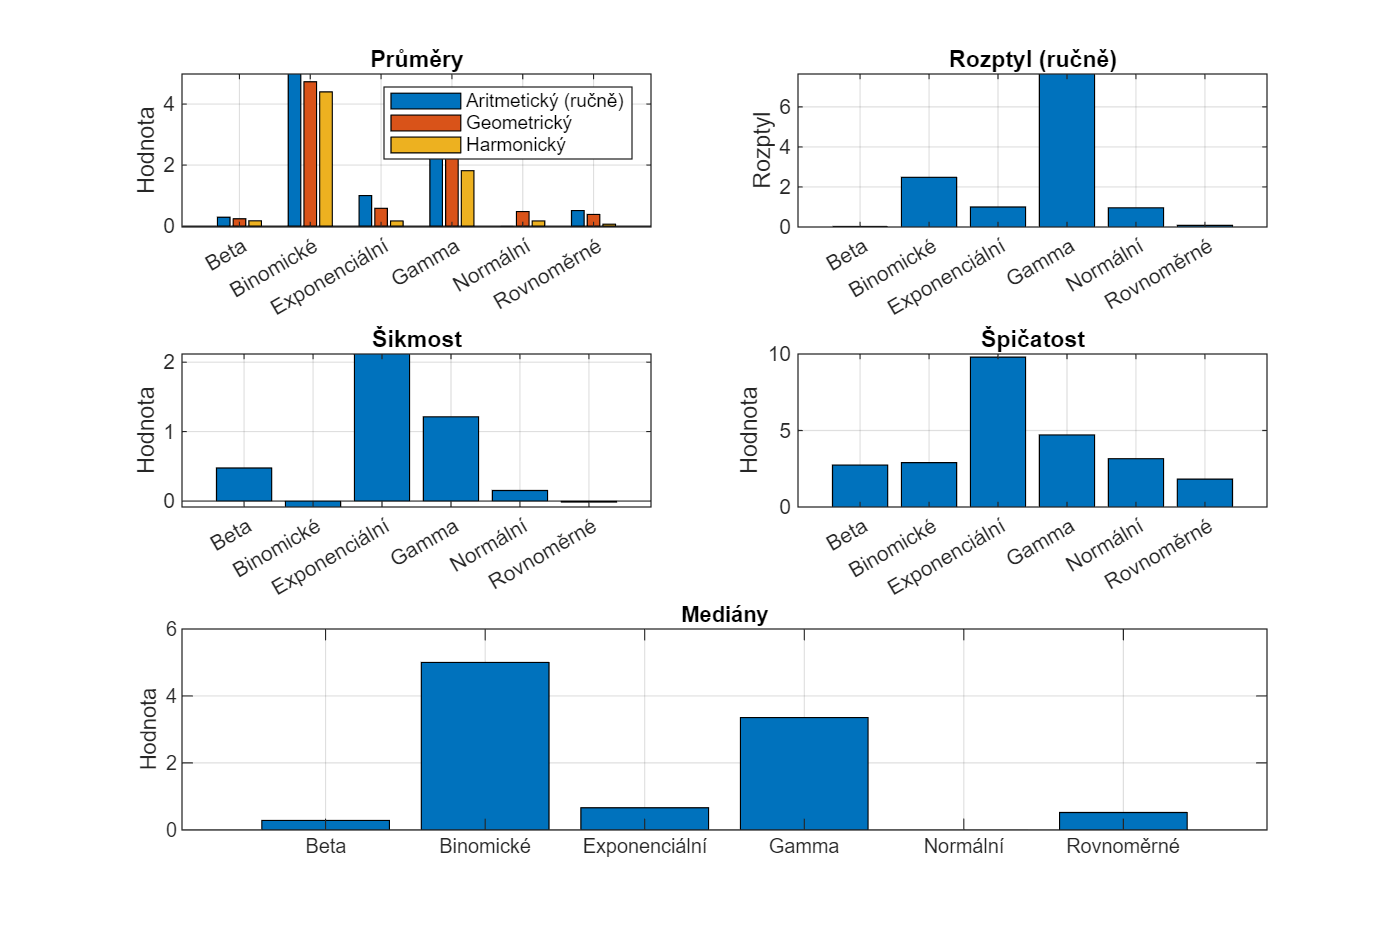


%% Srovnávací grafy pro přehled všech statistik
% Srovnání charakteristik mezi množinami v jediné figuře pomocí subplot

figure('Name', 'Srovnání všech charakteristik', 'Position', [100 100 1200 800]);

subplot(3,2,1);
bar(categorical(labels), [means_manual; geomeans; harmmeans]');
title('Průměry');
legend('Aritmetický (ručně)', 'Geometrický', 'Harmonický');
ylabel('Hodnota'); grid on;

subplot(3,2,2);
bar(categorical(labels), variances_manual);
title('Rozptyl (ručně)');
ylabel('Rozptyl'); grid on;

subplot(3,2,3);
bar(categorical(labels), skewnesses);
title('Šikmost');
ylabel('Hodnota'); grid on;

subplot(3,2,4);
bar(categorical(labels), kurtoses);
title('Špičatost');
ylabel('Hodnota'); grid on;

subplot(3,2,[5 6]);
bar(categorical(labels), medians);
title('Mediány');
ylabel('Hodnota'); grid on;

% Možnost uložení souhrnného grafu:
% Vytvoříme složku 'grafy', pokud ještě neexistuje
if ~exist('grafy', 'dir')
    mkdir('grafy');
end
saveas(gcf, fullfile('grafy', 'srovnani_charakteristik.png'));